%% ============================
%  LEITURA E PREPARAÇÃO
% ============================

data = readtable("C:\Users\gabri\Documents\UFMG\TCC\FEMM\lua\resultado\resultados.csv");

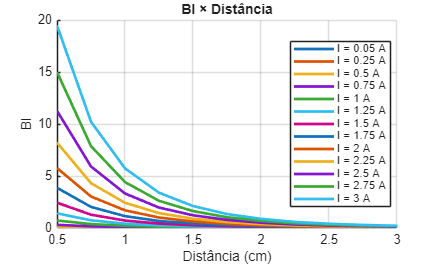



I  = data.Corrente_A_;
d  = -data.Distancia_cm_ / 100; % Distância em m (para consistência do conjunto de dados)
L  = data.Indutancia_H_;
Fm = data.ForcaFy_N_; % Força magnética medida (Fm)

% Quero ignorar as distâncias 0,05 e 0,25cm
d_ignorar = [0.0005, 0.0025];
filtro = ~ismember(d, d_ignorar);
% APLICAÇÃO DO FILTRO
I = I(filtro);
d = d(filtro);
Fm = Fm(filtro);

% Valores únicos
corrente_unificada = unique(I); % remover correntes duplicadas

% ============================================
% (Bl) × distancia
% ============================================
figure;
hold on;
grid on;

for k = 1:length(corrente_unificada)
    Ik = corrente_unificada(k);

    mask = (I == Ik);

    % sorted by distance
    [d_sorted, idx] = sort(d(mask));
    Fy_sorted = Fm(mask);
    Fy_sorted = Fy_sorted(idx);

    plot(d_sorted*100 , Fy_sorted * Ik, 'LineWidth', 2);
end


xlabel('Distância (cm)');
ylabel('Bl');
title('Bl × Distância');
legend("I = " + string(corrente_unificada) + " A", 'Location','best');
hold off;



%% ============================
% 2. REGRESSÃO DO MODELO BL
%     Bl = K_Bl * (I / x^2)
% ============================

% Simulação Bl = Fy / I
Bl_experimental = Fm ./ I;

Y_Bl = Bl_experimental;

% Variável independente
X_Bl = I ./ (d.^2);

% Regressão pelo operador barra
K_Bl = X_Bl \ Y_Bl;

% Predição
Y_Bl_modelo = X_Bl * K_Bl;

% R²
SS_residual = sum((Y_Bl - Y_Bl_modelo).^2);
SS_total    = sum((Y_Bl - mean(Y_Bl)).^2);
R_sq_Bl     = 1 - (SS_residual / SS_total);

disp('===========================================');

disp('📈 RESULTADOS DA REGRESSÃO DE BL (Operador Barra Invertida)');

📈 RESULTADOS DA REGRESSÃO DE BL (Operador Barra Invertida)


disp('===========================================');

disp(['Valor de K_Bl ajustado: ', num2str(K_Bl)]);

Valor de K_Bl ajustado: 1.8632e-05


disp(['R-quadrado (Qualidade do Ajuste): ', num2str(R_sq_Bl)]);

R-quadrado (Qualidade do Ajuste): 0.99159


disp(' ');

fprintf('Expressão Final Bl(x, I) = %.7f * (I / x^2)\n', K_Bl);

Expressão Final Bl(x, I) = 0.0000186 * (I / x^2)


disp('===========================================');

# VALIDAÇÃO DO MODELO

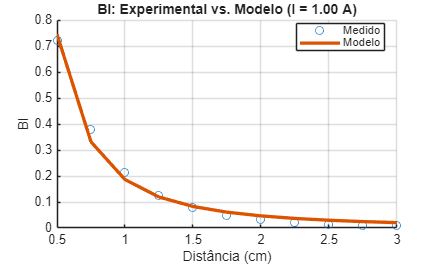

% Altere este índice para selecionar uma fatia de corrente diferente.
index_atual = 5;

% Valores únicos
corrente_unificada = unique(I);
d_unificado  = unique(d);

% Corrente selecionada
Ik = corrente_unificada(index_atual);

% Modelo teórico
Bl_modelo = K_Bl * (Ik ./ (d_unificado.^2));

% Ordenar por distância
ordenador = I == Ik;
[d_ordenado, idx] = sort(d(ordenador));
Fm_ordenado = Fm(ordenador);

% Bl experimental
Bl_experimental = Fm_ordenado * Ik;


%% ============================
%  PLOTAGEM
% ============================

figure;
hold on;
grid on;

% Experimental
plot(d_unificado *100, Bl_experimental, 'o', 'MarkerSize', 6, ...
    'DisplayName', 'Medido');

% Modelo
plot(d_unificado *100, Bl_modelo, '-', 'LineWidth', 2.5, ...
    'DisplayName', 'Modelo');

xlabel('Distância (cm)');
ylabel('Bl');
title(sprintf('Bl: Experimental vs. Modelo (I = %.2f A)', Ik));
legend('Location', 'best');

hold off;